# Pancreatic Cancer Biomarkers

## Dataset 1 - GSE42952

### Read in data from GEO

gse1=bmes_downloadandparsegse('GSE42952');

Reading C:\Users\Natha\AppData\Local\Temp\GSE42952.txt ...


get(gse1.Data);

            Name: ''
        RowNames: {54675×1 cell}
        ColNames: {1×33 cell}
           NRows: 54675
           NCols: 33
           NDims: 2
    ElementClass: 'double'



d1 = gse1.Data;

### Change row names to Gene symbols

gse1.Header.Series.platform_id;
gpl1 = bmes_downloadandparsegpl('GPL570');
gplprobes1 = gpl1.Data(:, strcmp(gpl1.ColumnNames, 'ID'));
gplgenes1  = gpl1.Data(:, strcmp(gpl1.ColumnNames, 'Gene Symbol'));
gseprobes1 = d1.rownames;
MAP_GSE_GPL1 = zeros(numel(gseprobes1),1);

%Uses a map container to convert each gseprobe to the genesymbol
map = containers.Map(gplprobes1,1:numel(gplprobes1));
for i=1:numel(gseprobes1)
	if map.isKey(gseprobes1{i}); MAP_GSE_GPL1(i)=map(gseprobes1{i}); end
end

gsegenes1 = gseprobes1;
gsegenes1(find(MAP_GSE_GPL1)) = gplgenes1(MAP_GSE_GPL1(find(MAP_GSE_GPL1)));

%Convert all the rownames in the data matrix to be the gene symbols
d1 = d1.rownames(':',gsegenes1);

### Index data into doubles matrix

idx_bad = contains(gse1.Header.Samples.description, 'bad');
idx_good = contains(gse1.Header.Samples.description, 'good');
idx_control1 = contains(gse1.Header.Samples.description, 'Gene expression data');
d1_temp = d1;
geneID_true = ~cellfun(@isempty,d1_temp.RowNames);
d1_temp = d1_temp(geneID_true,:);
idx_nan1 = isnan(d1_temp(:,1));
d1_parse = d1_temp(~idx_nan1,:);
control1 = d1_parse(:,idx_control1);
d_control_dub1 = double(control1);
d_bad = d1_parse(:,idx_bad);
d_bad_dub = double(d_bad);
d_good = d1_parse(:,idx_good);
d_good_dub = double(d_good);

### Fold Change control v cancer cells

d_foldchange_cancer_control1 = d1_parse.RowNames;
foldchange_cancer_control_sort1 =  d1_parse.RowNames;
d1_cancer_cells = horzcat(d_good_dub,d_bad_dub);
r=size(d1_cancer_cells);
for j = 1:r
    cntrl_avg= mean(d_control_dub1(j,:)); % find average of healthy 
    % deltaCT values
    pat_avg= mean(d1_cancer_cells(j,:)); % find average of patient 
    % deltaCT values
    deltadeltaCt = pat_avg-cntrl_avg; % calcualte deltadeltaCT values
    d_foldchange_cancer_control1(j,2) = {2^(-deltadeltaCt)};
    if d_foldchange_cancer_control1{j,2} < 1
        d_foldchange_cancer_control1(j,2) = {(-1)/d_foldchange_cancer_control1{j,2}};
    end
    foldchange_cancer_control_sort1(j,2) = {abs(d_foldchange_cancer_control1{j,2})};
end
foldchange_cancer_control_sort1 = sortrows(foldchange_cancer_control_sort1,2,'descend'); % sorts the table
% in descending order
sig_genes1 = foldchange_cancer_control_sort1; % outputs the 10 most up/down regulated RNAs
% if there are no gene symbols use gene probes

### P-value between control v cancer cells

p_vals_control_cancer1 = d1_parse.RowNames;
%p_vals_control_cancer1(EmptyCells)=[];
for i = 1:size(d_bad_dub)
    [~,p]=ttest2(d1_cancer_cells(i,:),d_control_dub1(i,:),'Alpha',0.01);
    p_vals_control_cancer1(i,2) = {p};
end
p_vals_control_cancer_sort1 = sortrows(p_vals_control_cancer1,2);
p_vals_control_cancer_sort1(1:20,:)

ans = 20×2 cell array
    {'CTNNB1'                  }    {[2.3598e-21]}
    {'BEND2'                   }    {[4.4774e-21]}
    {'SP1'                     }    {[5.0157e-21]}
    {'SERPINB6'                }    {[9.0163e-21]}
    {'RP11-369C8.1'            }    {[1.0226e-20]}
    {'MIR1244-3'               }    {[4.2975e-20]}
    {'TUBB1'                   }    {[5.1674e-20]}
    {'S100Z'                   }    {[8.3478e-20]}
    {'MSL2'                    }    {[8.6964e-20]}
    {'BCL2L2-PABPN1 /// PABPN1'}    {[1.2241e-19]}
    {'SKI'                     }    {[1.8403e-19]}
    {'TPP2'                    }    {[2.1387e-19]}
    {'YWHAH'                   }    {[2.3924e-19]}
    {'ATP6V0E1'                }    {[4.2313e-19]}
    {'NR1H4'                   }    {[4.3797e-19]}
    {'SRRM1'                   }    {[7.3488e-19]}


### Hypergeomtric Test

gplgobio1  = gpl1.Data(:, strcmp(gpl1.ColumnNames, 'Gene Ontology Biological Process'));
for i=1:numel(gplgobio1)
	%handle empty separately, b/c strsplit doesn't work as we want for empty strings.
	if isempty(gplgobio1{i}); gplgobio1{i}={};
	else gplgobio1{i} = strsplit(gplgobio1{i},' /// '); end
end

% Let's reduce amount of memory by keeping a master list of Biological
% Processes and have each probe have indices to that master list.
GOBIO1 = unique( [gplgobio1{:}]);

% And use the "map" technique to search for each term in the GOBIO list.
map = containers.Map(GOBIO1,1:numel(GOBIO1));
for i=1:numel(gplgobio1)
	for j=1:numel(gplgobio1{i})
		gplgobio1{i}{j} = map(gplgobio1{i}{j});
	end
	gplgobio1{i} = cell2mat(gplgobio1{i});
end

gsegobio1 = cell(size(d1,1),1); %any probe not found in gpl will remain an empty vector.
gsegobio1(find(MAP_GSE_GPL1)) = gplgobio1(MAP_GSE_GPL1(find(MAP_GSE_GPL1)));

for i = 1:size(p_vals_control_cancer1)
    Isig1(i)= p_vals_control_cancer1{i,2} <= 0.01;
end
Isig1 = logical(Isig1);
gsegobiosig1 = gsegobio1(Isig1);
candidategobio1 = unique( [gsegobiosig1{:}] )';

total_sig_genes = nnz(~cellfun(@isempty,gsegobiosig1));% Total number of significant genes. (ignore those with no GO term).
Num_genes = nnz(~cellfun(@isempty,gsegobio1));% Total number of genes. (ignore those with no GO term).
for i = 1:size(candidategobio1)
    num_sig_genes_term(i) = nnz([gsegobiosig1{:}] == candidategobio1(i)); % The number of significant genes that are in this term.
    total_num_genes_term(i) = nnz([gsegobio1{:}] == candidategobio1(i)); % Number of genes (significant or not) that are in this term.
    pval_hygecdf1(i,1) = {GOBIO1{candidategobio1(i)}};
    pval_hygecdf1(i,2) = {hygecdf(num_sig_genes_term(i),Num_genes,total_num_genes_term(i),total_sig_genes)};
end
pval_hygecdf1_sort = sortrows(pval_hygecdf1,2,"ascend")

pval_hygecdf1_sort = 5062×2 cell array
    {'0010467 // gene expression // traceable author statement'                                                    }    {[1.1028e-06]}
    {'0016071 // mRNA metabolic process // traceable author statement'                                             }    {[1.1278e-05]}
    {'0019058 // viral life cycle // traceable author statement'                                                   }    {[1.2666e-05]}
    {'0000184 // nuclear-transcribed mRNA catabolic process, nonsense-mediated decay // traceable author statement'}    {[2.0130e-05]}
    {'0006614 // SRP-dependent cotranslational protein targeting to membrane // traceable author statement'        }    {[3.6690e-05]}
    {'0007267 // cell-cell signaling // traceable author statement'                                                }    {[4.5707e-05]}
    {'0007165 // signal transduction // traceable author statement'                                                }    {[4.6928e-05]}
    {'0006412 //

## Dataset 2 - 

### Read in Excel Data

%% https://journals.plos.org/plosone/article?id=10.1371/journal.pone.0148807
d2 = readtable('Gysin_PDAC_Cells_mRNA_Data.xlsx');

### Fold Change

gene_names=table2array(d2(:,3));
controls= table2array(d2(:,4:9));
control_avg=mean(controls,2);
cancers=table2array(d2(:,10:end));
cancer_avg=mean(cancers,2);
Difference=cancer_avg-control_avg;
[r,~]=size(Difference);
Differential=gene_names;
for i=1:r
    Differential(i,2)={2^Difference(i)};
    if Differential{i,2} < 1%if fold change is less than 1, replace it with its negative inverse
        Differential(i,2) = {(-1)/Differential{i,2}};
    end
    Differential(i,2) = {abs(Differential{i,2})};%gets the absolute values to account for positive or negative change
end
change_sort = sortrows(Differential,2,'descend'); % Sort in descending value
sig_genes2=change_sort; % outputs the 100 most up/down regulated mirnas(abs value accounts for both positive and negative change)

### Significantly Different

p_vals_control_cancer = gene_names;
for i = 1:r
    [~,p]=ttest2(cancers(i,:),controls(i,:));
    p_vals_control_cancer(i,2) = {p};
end
p_vals_control_cancer_sort = sortrows(p_vals_control_cancer,2);
p_vals_control_cancer_sort(1:20,:);
writecell(p_vals_control_cancer_sort(1:6000,1),'sig_genes2_DAVID.txt')

## Dataset 3 - GSE32676

### Read in data from GEO

gse3=bmes_downloadandparsegse('GSE32676');

Reading C:\Users\Natha\AppData\Local\Temp\GSE32676.txt ...


get(gse3.Data);

            Name: ''
        RowNames: {54675×1 cell}
        ColNames: {1×32 cell}
           NRows: 54675
           NCols: 32
           NDims: 2
    ElementClass: 'double'



d3 = gse3.Data;

### Change row names to Gene symbols

gse3.Header.Series.platform_id;
gpl3 = bmes_downloadandparsegpl('GPL570');
gplprobes3 = gpl3.Data(:, strcmp(gpl3.ColumnNames, 'ID'));
gplgenes3  = gpl3.Data(:, strcmp(gpl3.ColumnNames, 'Gene Symbol'));
gseprobes3 = d3.rownames;
MAP_GSE_GPL3 = zeros(numel(gseprobes3),1);

%Uses a map container to convert each gseprobe to the genesymbol
map = containers.Map(gplprobes3,1:numel(gplprobes3));
for i=1:numel(gseprobes3)
	if map.isKey(gseprobes3{i}); MAP_GSE_GPL3(i)=map(gseprobes3{i}); end
end

gsegenes3 = gseprobes3;
gsegenes3(find(MAP_GSE_GPL3)) = gplgenes3(MAP_GSE_GPL3(find(MAP_GSE_GPL3)));

%Convert all the rownames in the data matrix to be the gene symbols
d3 = d3.rownames(':',gsegenes3);

### Index data into doubles matrix

idx_control3 = contains(gse3.Header.Samples.source_name_ch1, 'non-malignant pancreas');
idx_cancer3 = ~idx_control3;
control3 = d3(:,idx_control3);
cancer3 = d3(:,idx_cancer3);
d_control_cancer3 = double(control3);
d_cancer_cells3 = double(cancer3);

### Fold Change control v cancer cells

d_foldchange_cancer_control3 = d3.RowNames;
foldchange_cancer_control_sort3 = d3.RowNames;
r=size(d_control_cancer3);
for j = 1:r
    cntrl_avg= mean(d_control_cancer3(j,1:4)); % find average of healthy 
    % deltaCT values
    pat_avg= mean(d_control_cancer3(j,5:end)); % find average of patient 
    % deltaCT values
    deltadeltaCt = pat_avg - cntrl_avg; % calcualte deltadeltaCT values
    d_foldchange_cancer_control3(j,2) = {2^(-deltadeltaCt)};
    if d_foldchange_cancer_control3{j,2} < 1
        d_foldchange_cancer_control3(j,2) = {(-1)/d_foldchange_cancer_control3{j,2}};
    end
    foldchange_cancer_control_sort3(j,2) = {abs(d_foldchange_cancer_control3{j,2})};
end
foldchange_cancer_control_sort3 = sortrows(foldchange_cancer_control_sort3,2,'descend'); % sorts the table
% in descending order
sig_genes3 = foldchange_cancer_control_sort3; % outputs the 100 most up/down regulated RNAs
% if there are no gene symbols use gene probes

### P-value between control v cancer cells

p_vals_control_cancer3 = d3.RowNames;
for i = 1:r
    [~,p]=ttest2(d_cancer_cells3(i,:),d_control_cancer3(i,:));
    p_vals_control_cancer3(i,2) = {p};
end
p_vals_control_cancer_sort3 = sortrows(p_vals_control_cancer3,2);
p_vals_control_cancer_sort3(1:20,:);

### Hypergeomtric Test

gplgobio3  = gpl3.Data(:, strcmp(gpl3.ColumnNames, 'Gene Ontology Biological Process'));
for i=1:numel(gplgobio3)
	%handle empty separately, b/c strsplit doesn't work as we want for empty strings.
	if isempty(gplgobio3{i}); gplgobio3{i}={};
        
    else 
        gplgobio3{i} = strsplit(gplgobio3{i},' /// '); 
    end
end

% Let's reduce amount of memory by keeping a master list of Biological
% Processes and have each probe have indices to that master list.
GOBIO3 = unique( [gplgobio3{:}] );

% And use the "map" technique to search for each term in the GOBIO list.
map = containers.Map(GOBIO3,1:numel(GOBIO3));
for i=1:numel(gplgobio3)
	for j=1:numel(gplgobio3{i})
		gplgobio3{i}{j} = map(gplgobio3{i}{j});
	end
	gplgobio3{i} = cell2mat(gplgobio3{i});
end

gsegobio3 = cell(size(d3,1),1); %any probe not found in gpl will remain an empty vector.
gsegobio3(find(MAP_GSE_GPL3)) = gplgobio3(MAP_GSE_GPL3(find(MAP_GSE_GPL3)));

for i = 1:size(p_vals_control_cancer3)
    Isig3(i)= p_vals_control_cancer3{i,2}<=0.01;
end
Isig3 = logical(Isig3);
gsegobiosig3 = gsegobio3(Isig3);
candidategobio3 = unique( [gsegobiosig3{:}] )';

total_sig_genes = nnz(~cellfun(@isempty,gsegobiosig3));% Total number of significant genes. (ignore those with no GO term).
Num_genes = nnz(~cellfun(@isempty,gsegobio3));% Total number of genes. (ignore those with no GO term).
for i = 1:size(candidategobio3)
    num_sig_genes_term(i) = nnz([gsegobiosig3{:}] == candidategobio3(i)); % The number of significant genes that are in this term.
    total_num_genes_term(i) = nnz([gsegobio3{:}] == candidategobio3(i)); % Number of genes (significant or not) that are in this term.
    pval_hygecdf3(i,1) = {GOBIO3{candidategobio3(i)}};
    pval_hygecdf3(i,2) = {hygecdf(num_sig_genes_term(i),Num_genes,total_num_genes_term(i),total_sig_genes)};
end
pval_hygecdf3_sort = sortrows(pval_hygecdf3,2,"ascend")

pval_hygecdf3_sort = 8762×2 cell array
    {'0050896 // response to stimulus // inferred from electronic annotation'                                                  }    {[5.7711e-05]}
    {'0007389 // pattern specification process // inferred from electronic annotation'                                         }    {[2.0163e-04]}
    {'0000902 // cell morphogenesis // inferred from electronic annotation'                                                    }    {[2.4211e-04]}
    {'0090305 // nucleic acid phosphodiester bond hydrolysis // inferred from electronic annotation'                           }    {[4.2339e-04]}
    {'0050911 // detection of chemical stimulus involved in sensory perception of smell // inferred from electronic annotation'}    {[7.3197e-04]}
    {'0051084 // 'de novo' posttranslational protein folding // traceable author statement'                                    }    {[    0.0024]}
    {'0008380 // RNA splicing // traceable author statement'                   

## Drug Repurposing 

sig_gene_name1 = unique(string(sig_genes1(:,1)),'stable');
sig_gene_name1across = sig_gene_name1(1:526);
sig_gene_name2 = unique(string(sig_genes2(:,1)),'stable');
sig_gene_name2across = sig_gene_name2(1:526);
sig_gene_name3 = unique(string(sig_genes3(:,1)),'stable');
sig_gene_name3across = sig_gene_name3(1:526);
sig_gene_names_300 = string(vertcat(sig_gene_name1(1:100),sig_gene_name2(1:100),sig_gene_name3(1:100)));
same_btwn_1_2 = intersect(sig_gene_name1across,sig_gene_name2across);
same_btwn_all = intersect(same_btwn_1_2,sig_gene_name3across)

same_btwn_all = "FHL1"

% sig_gene_names_300(1) = strjoin(["Target:",sig_gene_names_300(1)]);
sig_gene_names_300 = strjoin((strcat("Target:",(sig_gene_names_300), ' OR ')),',')';
sig_gene_names_300 = replace(sig_gene_names_300,',',' ');
sig_gene_names_300 = char(sig_gene_names_300);
sig_gene_names_300 = string(sig_gene_names_300(1:end-3));
writematrix(sig_gene_names_300,'sig_genes.txt');
sig_gene_clue = unique(string(importdata("sig_genes_within_clue_io_database.txt")),'stable')';
sig_gene_idx = replace(sig_gene_clue,'Target:','');
sig_gene_clue = strjoin(strcat(sig_gene_clue, ' OR '));
writematrix(sig_gene_clue,'sig_genes_repurpose.txt');
drug_data = readtable("Repurposing_Hub_export.xlsx",'VariableNamingRule','preserve');
for i=1:size(drug_data.Target)
    drug_targets = strsplit(drug_data.Target{i},',');
    drug_targets = strtrim(drug_targets);
    matches = 0;
    save_gene = [];
    for j=1:numel(drug_targets)
        if nnz(strcmp(sig_gene_idx,drug_targets{j})) > 0
            matches = matches+1;
            save_gene(end+1) =j; 
        end
    end
    drug_data.score(i) = matches;
    if ~isempty(save_gene)
        drug_data.Target(i) = {strjoin(drug_targets(save_gene),',')};
    else
        drug_data.Target(i) = {'None'};
    end
end
drug_data = sortrows(drug_data,"score","descend")

drug_data = 253×5 table
                Name                                            MOA                                         Target                     Phase           score
    ____________________________    ___________________________________________________________    _________________________    ___________________    _____

    {'marimastat'              }    {'matrix metalloprotease inhibitor'                       }    {'MMP1,MMP10,MMP14,MMP7'}    {'Phase 3'        }      4  
    {'niflumic-acid'           }    {'cyclooxygenase inhibitor'                               }    {'KCNQ1,PLA2G1B,UGT1A9' }    {'Launched'       }      3  
    {'bardoxolone-methyl'      }    {'nuclear factor erythroid derived, like (NRF2) activator'}    {'PPARG,STAT3'          }    {'Phase 3'        }      2  
    {'cholic-acid'  

writetable(drug_data,'drug_data.xlsx','WriteMode','overwritesheet')

## Most Expressed Gene in all 3 Datasets 

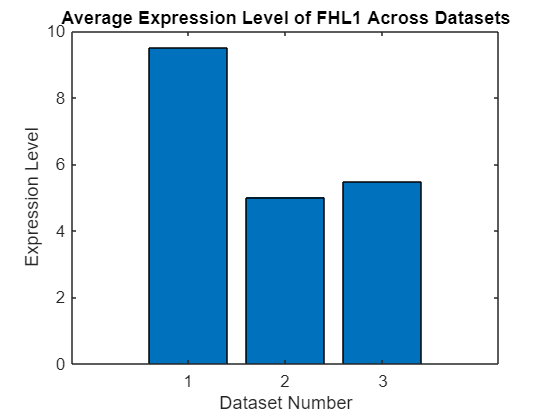

idx1 =find(contains(d1_parse.RowNames,same_btwn_all));
idx2 = find(contains(table2cell(d2(:,3)),same_btwn_all));
idx3 =find(contains(d3.RowNames,same_btwn_all));
avg_ENO1_express = [mean(mean(d1_cancer_cells(idx1,:))),mean(mean(cancers(idx2,:))),mean(mean(d_cancer_cells3(idx3,:)))];
bar(avg_ENO1_express)
xlabel('Dataset Number')
ylabel('Expression Level')
title('Average Expression Level of FHL1 Across Datasets')

## Information for Venn Diagram

sigfoldchange1 = sig_genes1(find(cell2mat(sig_genes1(:,2)) > 2),:);
sigfoldchange2 = sig_genes2(find(cell2mat(sig_genes2(:,2)) > 2),:);
sigfoldchange3 = sig_genes3(find(cell2mat(sig_genes3(:,2)) > 2),:);
numel(sigfoldchange1)

ans = 3004

numel(sigfoldchange2)

ans = 5450

numel(sigfoldchange3)

ans = 4554

intersect_raw_1_2 = numel(intersect(sigfoldchange1(:,1),sigfoldchange2(:,1)));
intersect_raw_2_3 = numel(intersect(sigfoldchange2(:,1),sigfoldchange3(:,1)));
intersect_raw_1_3 = numel(intersect(sigfoldchange1(:,1),sigfoldchange3(:,1)));
intersect_raw_all = numel(intersect(intersect(sigfoldchange1(:,1),sigfoldchange2(:,1)),sigfoldchange3(:,1)));